# Atividade 05_04

Otávio Baziewicz Filho - 1942808

## Clear Workspace

clear all;
close all;
clc;

## Filtro da mediana (função medfilt2)

Utilize o filtro da mediana com a função medfilt2 para remover o ruído sal-e-pimenta da imagem salt-and-pepper1.tif. Mostre as imagens de entrada e de saída (in vs. out) e compare com a saída de um filtro da média 3x3 e um filtro da média 5x5.

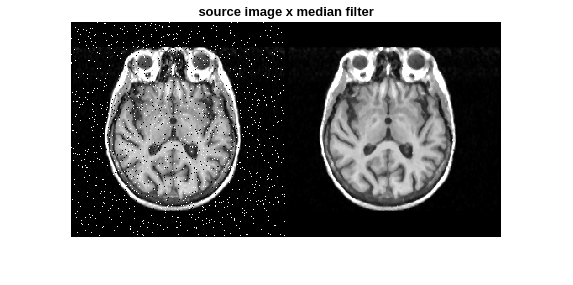

img = imread("salt-and-pepper1.tif");
medianImg = medfilt2(img);

kernel3x3 = fspecial("average", [3 3]);
kernel5x5 = fspecial("average", [5 5]);

boxFilter3x3 = imfilter(img, kernel3x3);
boxFilter5x5 = imfilter(img, kernel5x5);

figure, imshowpair(img, medianImg, "montage")
title("source image x median filter")

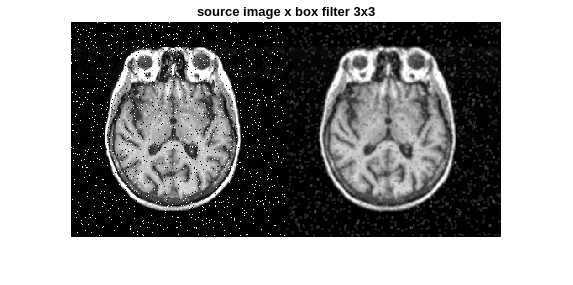


figure, imshowpair(img, boxFilter3x3, "montage")
title("source image x box filter 3x3")

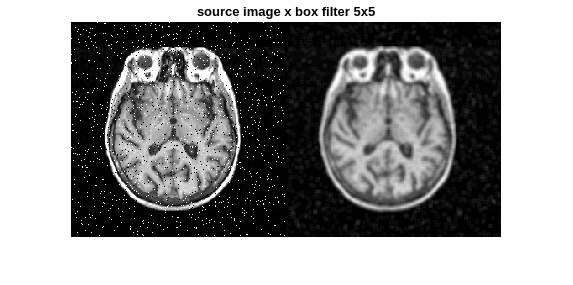


figure, imshowpair(img, boxFilter5x5, "montage")
title("source image x box filter 5x5")